# Resolución de Casos 4

## Caso 1

Definimos los valores de los distintos parámetros.

k_1 = 2;
k_2 = 1;

m_1 = 1;
m_2 = 2;

b_1 = 0.5;
b_2 = 0.2;

f = 1.0;

Definimos la matriz $b$.

b = [0 ; f/m_1 ; 0 ; 0]

b =      0
     1
     0
     0


Definimos la matriz $A$.

A = [0 1 0 0; 
    (-k_1/m_1) (-b_1/m_1) (k_1/m_1) (b_1/m_1);
    0 0 0 1;
    (k_1/m_2) (b_1/m_2) -(k_1 + k_2)/m_2 -(b_1 + b_2)/m_2]

A =          0    1.0000         0         0
   -2.0000   -0.5000    2.0000    0.5000
         0         0         0    1.0000
    1.0000    0.2500   -1.5000   -0.3500


### Problema 1

#### Determine si la matriz $A$ es diagonalizable. En caso no lo sea, plantee condiciones para que sí lo sea.

Obtenemos los vectores y valores propios de la matriz $A$.

[V, D] = eig(A)

V =    0.0927 + 0.4104i   0.0927 - 0.4104i  -0.6669 + 0.0000i  -0.6669 + 0.0000i
  -0.7511 + 0.0000i  -0.7511 + 0.0000i   0.0213 - 0.3730i   0.0213 + 0.3730i
  -0.0584 - 0.2417i  -0.0584 + 0.2417i  -0.5625 - 0.0027i  -0.5625 + 0.0027i
   0.4438 - 0.0067i   0.4438 + 0.0067i   0.0195 - 0.3145i   0.0195 + 0.3145i


D =   -0.3931 + 1.7411i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3931 - 1.7411i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0319 + 0.5593i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0319 - 0.5593i


Luego, obtenemos la determinante de la matriz $V$.

det(V)

ans = -0.6310 - 0.0000i

Finalmente, vemos que la determinante de la matriz de vectores propios es distinta de cero, ergo, son linealmente independientes.

### Problema 2

#### Resuelva el sistema de ecuaciones diferenciales.

Una solución complementaria $Z_c$ es...

syms t
Zc = V * exp(diag(D) * t)

Una solución particular $Z_p$ es...

q = [V(1, :) * exp(D(1, 1) * t)
     V(2, :) * exp(D(2, 2) * t)
     V(3, :) * exp(D(3, 3) * t)
     V(4, :) * exp(D(4, 4) * t)]

F = b

F =      0
     1
     0
     0


Zp = q * int(inv(q) * F) %#ok<MINV>

$$Zp = \left(\begin{array}{c} 0\\ \frac{885904025148915759191221600256}{7179912665123213703947899726645}-\frac{11771257202036657250172470820864}{21539737995369641111843699179935}\,\mathrm{i}\\ 0\\ 0 \end{array}\right)$$

La solución quedaría de la siguiente forma...

Z = Zc + Zp

x1 = matlabFunction(Z(1))

x1 = function_handle with value:
    @(t)exp(t.*(-3.931059663100753e-1-1.741103364747749i)).*(9.267057835519012e-2-4.104467233144751e-1i)+exp(t.*(-3.931059663100753e-1+1.741103364747749i)).*(9.267057835519012e-2+4.104467233144751e-1i)-exp(t.*(-3.189403368992416e-2-5.593376470412648e-1i)).*6.668897905337337e-1-exp(t.*(-3.189403368992416e-2+5.593376470412648e-1i)).*6.668897905337337e-1


x2 = matlabFunction(Z(3))

x2 = function_handle with value:
    @(t)exp(t.*(-3.931059663100753e-1-1.741103364747749i)).*(-5.842500693480041e-2+2.417131376792701e-1i)+exp(t.*(-3.931059663100753e-1+1.741103364747749i)).*(-5.842500693480041e-2-2.417131376792701e-1i)+exp(t.*(-3.189403368992416e-2-5.593376470412648e-1i)).*(-5.624566593481189e-1+2.728095024674814e-3i)+exp(t.*(-3.189403368992416e-2+5.593376470412648e-1i)).*(-5.624566593481189e-1-2.728095024674814e-3i)


### Problema 3

#### Grafique los resultados de las posiciones de las masas con respecto al tiempo proporcionado con las condiciones iniciales adecuadas. Explique el comportamiento de tales gráficos.

tp = 0:0.1:10

tp =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


gx1 = x1(tp)

gx1 =    -1.1484   -1.2887   -1.4149   -1.5238   -1.6125   -1.6793   -1.7227   -1.7423   -1.7381   -1.7110   -1.6623   -1.5937   -1.5074   -1.4059   -1.2920   -1.1684   -1.0379   -0.9035   -0.7676   -0.6328   -0.5013   -0.3750   -0.2555   -0.1439   -0.0413    0.0518    0.1353    0.2092    0.2738    0.3297    0.3778    0.4189    0.4540    0.4844    0.5111    0.5351    0.5576    0.5794    0.6014    0.6242    0.6485    0.6745    0.7025    0.7325    0.7644    0.7980    0.8329    0.8686    0.9046    0.9403


xlabel('t')
ylabel('x1')
plot(tp, gx1, 'r')
gx2 = x2(tp)

gx2 =    -1.2418   -1.1494   -1.0592   -0.9733   -0.8934   -0.8208   -0.7564   -0.7008   -0.6540   -0.6159   -0.5858   -0.5630   -0.5464   -0.5349   -0.5269   -0.5213   -0.5165   -0.5112   -0.5040   -0.4939   -0.4799   -0.4610   -0.4366   -0.4063   -0.3699   -0.3272   -0.2786   -0.2243   -0.1648   -0.1007   -0.0329    0.0379    0.1107    0.1846    0.2587    0.3322    0.4040    0.4734    0.5396    0.6021    0.6603    0.7138    0.7622    0.8053    0.8430    0.8753    0.9023    0.9242    0.9411    0.9533


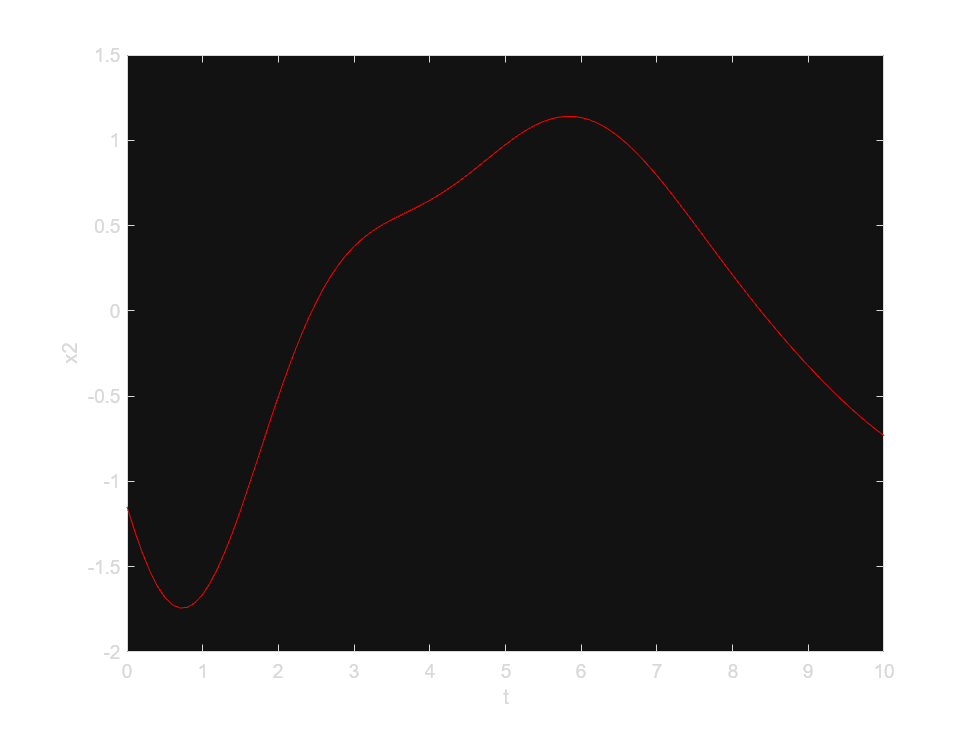

xlabel('t')
ylabel('x2')

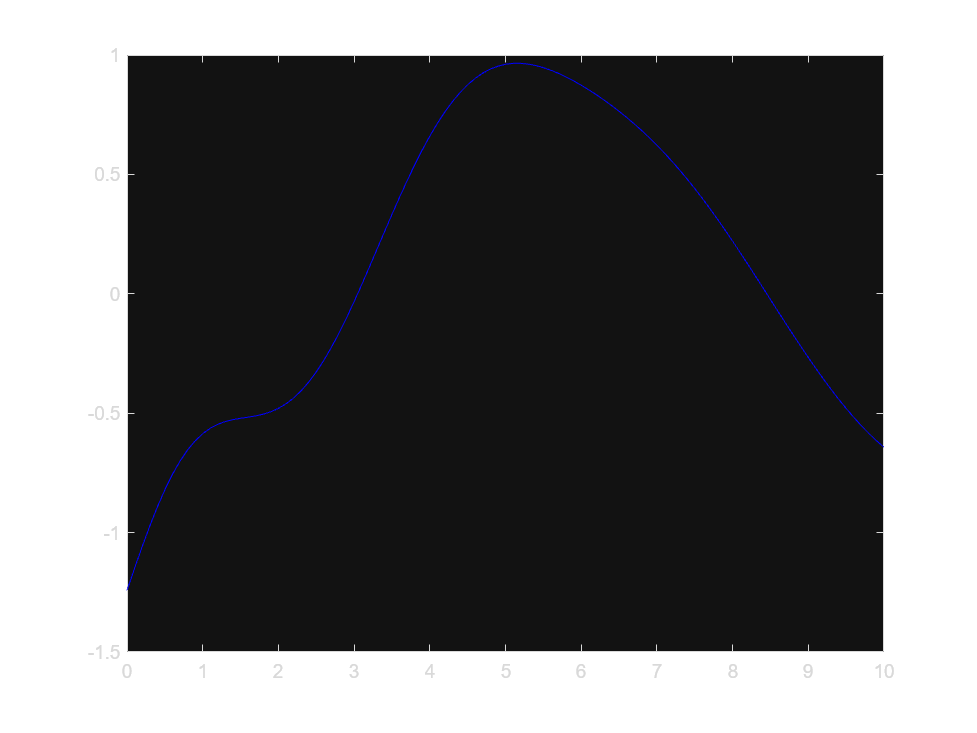

plot(tp, gx2, 'b')

## Caso 2

Definimos los valores de los distintos parámetros.

k_1 = 2;
k_2 = 1;

m_1 = 1;
m_2 = 2;

b_1 = 0.5;
b_2 = 0.2;

f = 1.0;

Definimos la matriz $b$.

b = [0 ; f/m_1 ; 0 ; 0]

b =      0
     1
     0
     0


Definimos la matriz $A$.

A = [0 1 0 0; 
    (-k_1/m_1) (-b_1/m_1) (k_1/m_1) (b_1/m_1);
    0 0 0 1;
    (k_1/m_2) (b_1/m_2) -(k_1 + k_2)/m_2 -(b_1 + b_2)/m_2]

A =          0    1.0000         0         0
   -2.0000   -0.5000    2.0000    0.5000
         0         0         0    1.0000
    1.0000    0.2500   -1.5000   -0.3500


### Problema 1

#### Determine si la matriz $A$ es diagonalizable. En caso no lo sea, plantee condiciones para que sí lo sea.

Obtenemos los vectores y valores propios de la matriz $A$.

[V, D] = eig(A)

V =    0.0927 + 0.4104i   0.0927 - 0.4104i  -0.6669 + 0.0000i  -0.6669 + 0.0000i
  -0.7511 + 0.0000i  -0.7511 + 0.0000i   0.0213 - 0.3730i   0.0213 + 0.3730i
  -0.0584 - 0.2417i  -0.0584 + 0.2417i  -0.5625 - 0.0027i  -0.5625 + 0.0027i
   0.4438 - 0.0067i   0.4438 + 0.0067i   0.0195 - 0.3145i   0.0195 + 0.3145i


D =   -0.3931 + 1.7411i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3931 - 1.7411i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0319 + 0.5593i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0319 - 0.5593i


Luego, obtenemos la determinante de la matriz $V$.

det(V)

ans = -0.6310 - 0.0000i

Finalmente, vemos que la determinante de la matriz de vectores propios es distinta de cero, ergo, son linealmente independientes.

### Problema 2

#### Resuelva el sistema de ecuaciones diferenciales.

Una solución complementaria $Z_c$ es...

syms t
Zc = V * exp(diag(D) * t)

Una solución particular $Z_p$ es...

q = [V(1, :) * exp(D(1, 1) * t)
     V(2, :) * exp(D(2, 2) * t)
     V(3, :) * exp(D(3, 3) * t)
     V(4, :) * exp(D(4, 4) * t)]

F = b

F =      0
     1
     0
     0


Zp = q * int(inv(q) * F) %#ok<MINV>

$$Zp = \left(\begin{array}{c} 0\\ \frac{885904025148915759191221600256}{7179912665123213703947899726645}-\frac{11771257202036657250172470820864}{21539737995369641111843699179935}\,\mathrm{i}\\ 0\\ 0 \end{array}\right)$$

La solución quedaría de la siguiente forma...

Z = Zc + Zp

x1 = matlabFunction(Z(1))

x1 = function_handle with value:
    @(t)exp(t.*(-3.931059663100753e-1-1.741103364747749i)).*(9.267057835519012e-2-4.104467233144751e-1i)+exp(t.*(-3.931059663100753e-1+1.741103364747749i)).*(9.267057835519012e-2+4.104467233144751e-1i)-exp(t.*(-3.189403368992416e-2-5.593376470412648e-1i)).*6.668897905337337e-1-exp(t.*(-3.189403368992416e-2+5.593376470412648e-1i)).*6.668897905337337e-1


x2 = matlabFunction(Z(3))

x2 = function_handle with value:
    @(t)exp(t.*(-3.931059663100753e-1-1.741103364747749i)).*(-5.842500693480041e-2+2.417131376792701e-1i)+exp(t.*(-3.931059663100753e-1+1.741103364747749i)).*(-5.842500693480041e-2-2.417131376792701e-1i)+exp(t.*(-3.189403368992416e-2-5.593376470412648e-1i)).*(-5.624566593481189e-1+2.728095024674814e-3i)+exp(t.*(-3.189403368992416e-2+5.593376470412648e-1i)).*(-5.624566593481189e-1-2.728095024674814e-3i)


### Problema 3

#### Grafique los resultados de las posiciones de las masas con respecto al tiempo proporcionado con las condiciones iniciales adecuadas. Explique el comportamiento de tales gráficos.

tp = 0:0.1:10

tp =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


gx1 = x1(tp)

gx1 =    -1.1484   -1.2887   -1.4149   -1.5238   -1.6125   -1.6793   -1.7227   -1.7423   -1.7381   -1.7110   -1.6623   -1.5937   -1.5074   -1.4059   -1.2920   -1.1684   -1.0379   -0.9035   -0.7676   -0.6328   -0.5013   -0.3750   -0.2555   -0.1439   -0.0413    0.0518    0.1353    0.2092    0.2738    0.3297    0.3778    0.4189    0.4540    0.4844    0.5111    0.5351    0.5576    0.5794    0.6014    0.6242    0.6485    0.6745    0.7025    0.7325    0.7644    0.7980    0.8329    0.8686    0.9046    0.9403


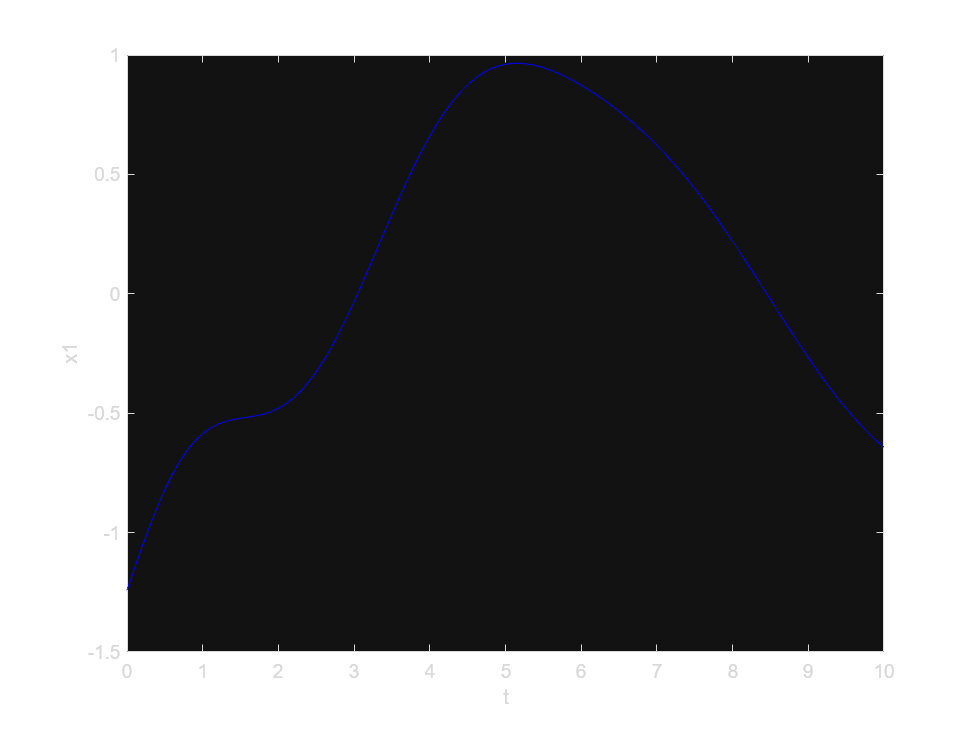

xlabel('t')
ylabel('x1')

plot(tp, gx1, 'r')
gx2 = x2(tp)

gx2 =    -1.2418   -1.1494   -1.0592   -0.9733   -0.8934   -0.8208   -0.7564   -0.7008   -0.6540   -0.6159   -0.5858   -0.5630   -0.5464   -0.5349   -0.5269   -0.5213   -0.5165   -0.5112   -0.5040   -0.4939   -0.4799   -0.4610   -0.4366   -0.4063   -0.3699   -0.3272   -0.2786   -0.2243   -0.1648   -0.1007   -0.0329    0.0379    0.1107    0.1846    0.2587    0.3322    0.4040    0.4734    0.5396    0.6021    0.6603    0.7138    0.7622    0.8053    0.8430    0.8753    0.9023    0.9242    0.9411    0.9533


xlabel('t')
ylabel('x2')

plot(tp, gx2, 'b')

## Caso 3

Definimos los valores de los distintos parámetros.

k_1 = 2;
k_2 = 1;

m_1 = 1;
m_2 = 2;

b_1 = 0.5;
b_2 = 0.2;

f = 1.0;

Definimos la matriz $b$.

b = [0 ; f/m_1 ; 0 ; 0]

b =      0
     1
     0
     0


Definimos la matriz $A$.

A = [0 1 0 0; 
    (-k_1/m_1) (-b_1/m_1) (k_1/m_1) (b_1/m_1);
    0 0 0 1;
    (k_1/m_2) (b_1/m_2) -(k_1 + k_2)/m_2 -(b_1 + b_2)/m_2]

A =          0    1.0000         0         0
   -2.0000   -0.5000    2.0000    0.5000
         0         0         0    1.0000
    1.0000    0.2500   -1.5000   -0.3500


### Problema 1

#### Determine si la matriz $A$ es diagonalizable. En caso no lo sea, plantee condiciones para que sí lo sea.

Obtenemos los vectores y valores propios de la matriz $A$.

[V, D] = eig(A)

V =    0.0927 + 0.4104i   0.0927 - 0.4104i  -0.6669 + 0.0000i  -0.6669 + 0.0000i
  -0.7511 + 0.0000i  -0.7511 + 0.0000i   0.0213 - 0.3730i   0.0213 + 0.3730i
  -0.0584 - 0.2417i  -0.0584 + 0.2417i  -0.5625 - 0.0027i  -0.5625 + 0.0027i
   0.4438 - 0.0067i   0.4438 + 0.0067i   0.0195 - 0.3145i   0.0195 + 0.3145i


D =   -0.3931 + 1.7411i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3931 - 1.7411i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0319 + 0.5593i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0319 - 0.5593i


Luego, obtenemos la determinante de la matriz $V$.

det(V)

ans = -0.6310 - 0.0000i

Finalmente, vemos que la determinante de la matriz de vectores propios es distinta de cero, ergo, son linealmente independientes.

### Problema 2

#### Resuelva el sistema de ecuaciones diferenciales.

Una solución complementaria $Z_c$ es...

syms t
Zc = V * exp(diag(D) * t)

Una solución particular $Z_p$ es...

q = [V(1, :) * exp(D(1, 1) * t)
     V(2, :) * exp(D(2, 2) * t)
     V(3, :) * exp(D(3, 3) * t)
     V(4, :) * exp(D(4, 4) * t)]

F = b

F =      0
     1
     0
     0


Zp = q * int(inv(q) * F) %#ok<MINV>

$$Zp = \left(\begin{array}{c} 0\\ \frac{885904025148915759191221600256}{7179912665123213703947899726645}-\frac{11771257202036657250172470820864}{21539737995369641111843699179935}\,\mathrm{i}\\ 0\\ 0 \end{array}\right)$$

La solución quedaría de la siguiente forma...

Z = Zc + Zp

x1 = matlabFunction(Z(1))

x1 = function_handle with value:
    @(t)exp(t.*(-3.931059663100753e-1-1.741103364747749i)).*(9.267057835519012e-2-4.104467233144751e-1i)+exp(t.*(-3.931059663100753e-1+1.741103364747749i)).*(9.267057835519012e-2+4.104467233144751e-1i)-exp(t.*(-3.189403368992416e-2-5.593376470412648e-1i)).*6.668897905337337e-1-exp(t.*(-3.189403368992416e-2+5.593376470412648e-1i)).*6.668897905337337e-1


x2 = matlabFunction(Z(3))

x2 = function_handle with value:
    @(t)exp(t.*(-3.931059663100753e-1-1.741103364747749i)).*(-5.842500693480041e-2+2.417131376792701e-1i)+exp(t.*(-3.931059663100753e-1+1.741103364747749i)).*(-5.842500693480041e-2-2.417131376792701e-1i)+exp(t.*(-3.189403368992416e-2-5.593376470412648e-1i)).*(-5.624566593481189e-1+2.728095024674814e-3i)+exp(t.*(-3.189403368992416e-2+5.593376470412648e-1i)).*(-5.624566593481189e-1-2.728095024674814e-3i)


### Problema 3

#### Grafique los resultados de las posiciones de las masas con respecto al tiempo proporcionado con las condiciones iniciales adecuadas. Explique el comportamiento de tales gráficos.

tp = 0:0.1:10

tp =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


gx1 = x1(tp)

gx1 =    -1.1484   -1.2887   -1.4149   -1.5238   -1.6125   -1.6793   -1.7227   -1.7423   -1.7381   -1.7110   -1.6623   -1.5937   -1.5074   -1.4059   -1.2920   -1.1684   -1.0379   -0.9035   -0.7676   -0.6328   -0.5013   -0.3750   -0.2555   -0.1439   -0.0413    0.0518    0.1353    0.2092    0.2738    0.3297    0.3778    0.4189    0.4540    0.4844    0.5111    0.5351    0.5576    0.5794    0.6014    0.6242    0.6485    0.6745    0.7025    0.7325    0.7644    0.7980    0.8329    0.8686    0.9046    0.9403


xlabel('t')
ylabel('x1')

plot(tp, gx1, 'r')
gx2 = x2(tp)

gx2 =    -1.2418   -1.1494   -1.0592   -0.9733   -0.8934   -0.8208   -0.7564   -0.7008   -0.6540   -0.6159   -0.5858   -0.5630   -0.5464   -0.5349   -0.5269   -0.5213   -0.5165   -0.5112   -0.5040   -0.4939   -0.4799   -0.4610   -0.4366   -0.4063   -0.3699   -0.3272   -0.2786   -0.2243   -0.1648   -0.1007   -0.0329    0.0379    0.1107    0.1846    0.2587    0.3322    0.4040    0.4734    0.5396    0.6021    0.6603    0.7138    0.7622    0.8053    0.8430    0.8753    0.9023    0.9242    0.9411    0.9533


xlabel('t')
ylabel('x2')

plot(tp, gx2, 'b')